## Clean Workspace

clear;
close;
clc;

## System Model

**Mass-Damper-Spring System**

- m = mass

- c = damping coefficient

- k = spring constant

% Nominal system matrices
A_0 = [0 1;0 0];
B_0 = [0 1]';
C_0 = [1 0];
D_0 = 0;
E_0 = [1 0;0 0];
S_0 = ltisys(A_0,B_0,C_0,D_0,E_0);

% Affine dependence on m
A_m = [0 0;0 0];
B_m = [0 0]';
C_m = [0 0];
D_m = 0;
E_m = [0 0;0 1];
S_m = ltisys(A_m,B_m,C_m,D_m,E_m);

% Affine dependence on k
A_k = [0 0;-1 0];
B_k = [0 0]';
C_k = [0 0];
D_k = 0;
E_k = [0 0;0 0];
S_k = ltisys(A_k,B_k,C_k,D_k,0);

% Affine dependence on c
A_c = [0 0;0 -1];
B_c = [0 0]';
C_c = [0 0];
D_c = 0;
E_c = [0 0;0 0];
S_c = ltisys(A_c,B_c,C_c,D_c,0);

% m ∈ [1.8, 4.2], k ∈ [1.4, 2.6], c ∈ [0.8, 1.2]
pv_mds = pvec('box',[1.8 4.2; 1.4 2.6; 0.8 1.2]); % Range of parameter variation
pvinfo(pv_mds)

Vector of 3 parameters ranging in a box




% Parameter-dependent (uncertain) plant with affine dependence on m, k and c
pds_mds = psys(pv_mds, [S_0 S_m S_k S_c]);

psinfo(pds_mds)

Affine parameter-dependent model with 3 parameters (4 systems) 
    Each system has 2 state(s), 1 input(s), and 1 output(s)



## Robust Stability Analysis

% Test robust stability of the system via parametric Lyapunov functions
[tmin, Q0, Q1, Q2, Q3] = pdlstab(pds_mds, [0 0])


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                       -0.024610

 Result:  best value of t:    -0.024610
          f-radius saturation:  0.000% of R =  1.00e+07
 
 This system is stable for the specified parameter trajectories


tmin = -0.0246

Q0 =     1.6750   -0.3994
   -0.3994    1.1642


Q1 =     0.8456   -0.0451
   -0.0451   -0.0271


Q2 =     0.0543   -0.0989
   -0.0989    0.9498


Q3 =     0.6545   -0.7452
   -0.7452   -0.0235


## System Simulation

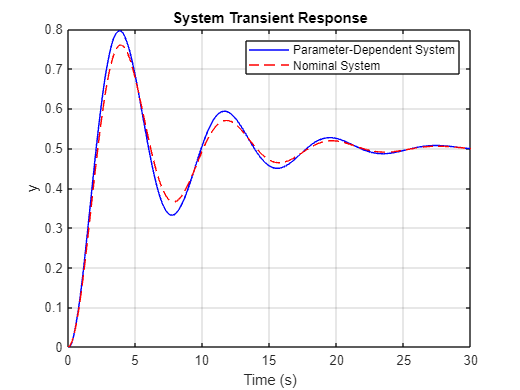

% Time response of mass–damper–spring system for the given parameter trajectory
[t,x,y] = pdsimul(pds_mds,'MDS_Parameters',30);

% Time response of the nominal mass–damper–spring system
mds_nom = psinfo(pds_mds, 'eval', [3 2 1]);
[a,b,c,d] = ltiss(mds_nom); mds_ss = ss(a,b,c,d);
tt = 0:0.01:30;
y_nom = step(mds_ss,tt);

% Plot
figure(1)
plot(t,y(:,1),'b-',tt,y_nom,'r--'), grid
xlabel('Time (s)')
ylabel('y')
title('System Transient Response')
legend('Parameter-Dependent System','Nominal System')